# Slosh 3D - Parametrization ZY

ZY Parametrization of the spherical pendulum

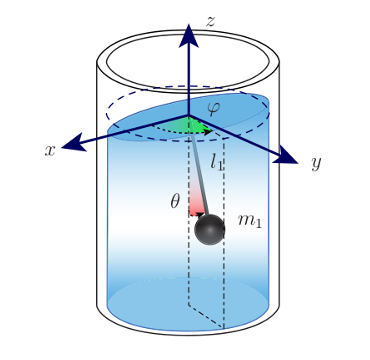

In this code the equation of motion for the pendulum angles representing the sloshing are derived through the use of the Euler-Lagrange equations.

This sloshing model represent the 3D motion of the pivot, but it is the same for any point with a displacement along z of the cylinder axis.

clc 
clear all

syms theta(t) phi(t)
syms t 
syms h l m g b
syms x(t) y(t) z(t) 

$\theta$ = second rotation about Y describing the sloshing

$\phi$ = first rotation abouy Z describing the plane of sloshing

l = length of pendulum

m = mass of pendulum

h = height of the liquid

b = damping coefficienr

## Derivation of the pendulum coordinates

Through the use of homogeneous transformation matrices infer the position of the pendulum mass and of the liquid mass in the world reference frame. 

Use of the parametrization using 3-2-3 euler angle convention. Note: to have the mass lying in the positive quadrant (x and y positive) the second rotation about y is taken in the opposite direction.

### Homogeneous Transformation from inertial frame to pivot

% First rotation about z
R_z_phi = [cos(phi),  -sin(phi), 0;
           sin(phi),   cos(phi), 0;
           0,          0,        1];

% Second rotation about y
R_y_theta = [cos(-theta),  0,  sin(-theta);
              0,            1,            0;
             -sin(-theta),  0,  cos(-theta)];

% Third rotation about z
R_z_phi_minus = [cos(-phi),  -sin(-phi), 0;
               sin(-phi),   cos(-phi), 0;
               0,          0,        1];

R = R_z_phi * R_y_theta * R_z_phi_minus

$$R(t) = \left(\begin{array}{ccc} \cos\left(\theta \left(t\right)\right)\,{\cos\left(\varphi \left(t\right)\right)}^{2}+{\sin\left(\varphi \left(t\right)\right)}^{2} & \cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)-\cos\left(\varphi \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right) & -\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\\ \cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)-\cos\left(\varphi \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right) & {\cos\left(\varphi \left(t\right)\right)}^{2}+\cos\left(\theta \left(t\right)\right)\,{\sin\left(\varphi \left(t\right)\right)}^{2} & -\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\\ \cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & \sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & \cos\left(\theta \left(t\right)\right) \end{array}\right)$$

Define translation vector (position of the pivot wrt inertial frame)

p = [x(t); y(t); z(t)];

Define the transformation

T_wp = [R, p; 0 0 0 1];
T_wp = formula(T_wp);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from world to pivot:');

Homogeneous Transformation Matrix from world to pivot:


disp(T_wp);

$$\left(\begin{array}{cccc} \cos\left(\theta \left(t\right)\right)\,{\cos\left(\varphi \left(t\right)\right)}^{2}+{\sin\left(\varphi \left(t\right)\right)}^{2} & \cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)-\cos\left(\varphi \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right) & -\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & x\left(t\right)\\ \cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)-\cos\left(\varphi \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right) & {\cos\left(\varphi \left(t\right)\right)}^{2}+\cos\left(\theta \left(t\right)\right)\,{\sin\left(\varphi \left(t\right)\right)}^{2} & -\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & y\left(t\right)\\ \cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & \sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & \cos\left(\theta \left(t\right)\right) & z\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$


$$p_m =$$

$$\left(\begin{array}{c}
l\,\cos \left(\phi \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\\
l\,\sin \left(\phi \left(t\right)\right)\sin \left(\theta \left(t\right)\right)\\
-l\,\cos \left(\theta \left(t\right)\right)
\end{array}\right)$$


### Homogeneous Transformation from pivot to mass

Define translation vector

p = [0; 0; -l];

Homogeneous transformation

T_pm = [eye(3), p; 0 0 0 1];
T_pm = formula(T_pm);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from pivot to mass:');

Homogeneous Transformation Matrix from pivot to mass:


disp(T_pm);

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & -l\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Pendulum mass coordinates in inertial frame

Derive the homogeneous transformation from inertial frame to pendulum mass.

T_wm = T_wp*T_pm;

Derive the coordinates of the pendulum mass

xm = T_wm(1,4)

$$xm = x\left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)$$

ym = T_wm(2,4)

$$ym = y\left(t\right)+l\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)$$

zm = T_wm(3,4)

$$zm = z\left(t\right)-l\,\cos\left(\theta \left(t\right)\right)$$

Define coordinate of pendulum mass wrt pivot

xr = l*cos(phi)*sin(theta)

$$xr(t) = l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)$$

yr = l*sin(phi)*sin(theta)

$$yr(t) = l\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)$$

zr = -l*cos(theta)

$$zr(t) = -l\,\cos\left(\theta \left(t\right)\right)$$


$$x_m =\;x\left(t\right)+l\,\cos \left(\phi \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)$$



$$y_{m\;} =\;y\left(t\right)+l\,\sin \left(\phi \left(t\right)\right)\sin \left(\theta \left(t\right)\right)$$



$$z_m =\;z\left(t\right)-l\,\cos \left(\theta \left(t\right)\right)$$


## Derivation of the equations of motion

Derive the equation of motion finding kinetic and potential energies and then assembling the lagrangian equation with respect to theta.

### Kinetic Energy

xm_dot = diff(xm, t);
ym_dot = diff(ym, t);
zm_dot = diff(zm, t);

xr_dot = diff(xr, t);
yr_dot = diff(yr, t);
zr_dot = diff(zr, t);

#### Kinetic energy for the pendulum

Sum the contributions of the kinetic energies in x, y and z

Tmx = 0.5 * m * xm_dot^2;
Tmx = simplify(Tmx)

$$Tmx = \frac{m\,{\left(\frac{\partial }{\partial t}x\left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-l\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}}{2}$$

%disp(latex(Tmx))

Tmy = 0.5 * m * ym_dot^2;
Tmy = simplify(Tmy)

$$Tmy = \frac{m\,{\left(\frac{\partial }{\partial t}y\left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}$$

%disp(latex(Tmx))

Tmz = 0.5 * m * zm_dot^2;
Tmz = simplify(Tmz)

$$Tmz = \frac{m\,{\left(\frac{\partial }{\partial t}z\left(t\right)+l\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}$$

%disp(latex(Tmz))

Tm = Tmx + Tmy + Tmz

$$Tm = \frac{m\,{\left(\frac{\partial }{\partial t}z\left(t\right)+l\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+\frac{m\,{\left(\frac{\partial }{\partial t}x\left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-l\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}}{2}+\frac{m\,{\left(\frac{\partial }{\partial t}y\left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}$$

T = Tm;


$$T_{m\;} =\;\frac{m\,{{\left(\frac{\partial }{\partial t}\mathrm{\ }z\left(t\right)+l\,\sin \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\theta \left(t\right)\right)}}^2 }{2}+\frac{m\,{{\left(\frac{\partial }{\partial t}\mathrm{\ }x\left(t\right)+l\,\cos \left(\phi \left(t\right)\right)\,\cos \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\theta \left(t\right)-l\,\sin \left(\phi \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\phi \left(t\right)\right)}}^2 }{2}+\frac{m\,{{\left(\frac{\partial }{\partial t}\mathrm{\ }y\left(t\right)+l\,\cos \left(\phi \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\phi \left(t\right)+l\,\cos \left(\theta \left(t\right)\right)\,\sin \left(\phi \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\theta \left(t\right)\right)}}^2 }{2}$$


### Potential energy

%% Potential energy
Um = m * g * zm;

U = Um;
U = simplify(U);
disp("Potential energy:");

Potential energy:


disp(U);

$$g\,m\,\left(z\left(t\right)-l\,\cos\left(\theta \left(t\right)\right)\right)$$


$$U=g\,m\,{\left(z\left(t\right)-l\,\cos \left(\theta \left(t\right)\right)\right)}$$


### Rayleigh function

To account for dissipied energy

theta_dot = diff(theta, t);
phi_dot = diff(phi, t);

v2 = xr_dot^2 + yr_dot^2+ zr_dot^2

$$v2(t) = {\left(l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+{\left(l\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-l\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}+l^{2}\,{\sin\left(\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}$$


D = b/2 *(v2);

D_dthetadot = diff(D, theta_dot);
D_dphidot = diff(D, phi_dot);

### Lagrangian

%% Lagrangian 
L = T - U;
L = simplify(L)

$$L = \frac{m\,{\left(\frac{\partial }{\partial t}z\left(t\right)+l\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+\frac{m\,{\left(\frac{\partial }{\partial t}x\left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-l\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}}{2}+\frac{m\,{\left(\frac{\partial }{\partial t}y\left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}-g\,m\,\left(z\left(t\right)-l\,\cos\left(\theta \left(t\right)\right)\right)$$


% wrt theta
L_thetadot = diff(L, diff(theta(t), t));
L_thetadot = simplify(L_thetadot);

dL_theta_dot = diff(L_thetadot, t);
dL_theta_dot = simplify(dL_theta_dot);

L_theta = diff(L, theta(t));
L_theta = simplify(L_theta)

$$L\_theta = m\,\left(l\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)-l\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)\,\left(\frac{\partial }{\partial t}y\left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)-m\,\left(l\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)\,\left(\frac{\partial }{\partial t}x\left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-l\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)-g\,l\,m\,\sin\left(\theta \left(t\right)\right)+l\,m\,\cos\left(\theta \left(t\right)\right)\,\left(\frac{\partial }{\partial t}z\left(t\right)+l\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)$$


% wrt phi
L_phi_dot = diff(L, diff(phi(t), t));
L_phi_dot = simplify(L_phi_dot);

dL_phi_dot = diff(L_phi_dot, t);
dL_phi_dot = simplify(dL_phi_dot);

L_phi = diff(L, phi(t));
L_phi = simplify(L_phi);

### Equation of motion

%for theta, that represents the swing of the pendulum and, accordingly, the sloshing dynamics.
eqn_theta = dL_theta_dot - L_theta + D_dthetadot;
% eqn_theta = eqn_theta + b * diff(theta, t);
eqn_theta = simplify(eqn_theta);
disp("Equation of motion with respect to theta:");

Equation of motion with respect to theta:


disp(eqn_theta);

$$b\,l^{2}\,\frac{\partial }{\partial t}\theta \left(t\right)+l^{2}\,m\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+l\,m\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}z\left(t\right)+g\,l\,m\,\sin\left(\theta \left(t\right)\right)+l\,m\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+l\,m\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)-l^{2}\,m\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}$$

disp("Latex Equation of motion with respect to theta:");

Latex Equation of motion with respect to theta:


disp(latex(eqn_theta));

b\,l^2\,\frac{\partial }{\partial t} \theta \left(t\right)+l^2\,m\,\frac{\partial ^2}{\partial t^2} \theta \left(t\right)+l\,m\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} z\left(t\right)+g\,l\,m\,\sin\left(\theta \left(t\right)\right)+l\,m\,\cos\left(\phi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} x\left(t\right)+l\,m\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\phi \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} y\left(t\right)-l^2\,m\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t} \phi \left(t\right)\right)}^2



syms c_theta s_theta c_phi s_phi
syms theta_dot theta_ddot phi_dot phi_ddot x_ddot y_ddot z_ddot 
eq_sub1 = subs(eqn_theta,[cos(theta(t)), sin(theta(t)), cos(phi(t)),sin(phi(t))],[c_theta s_theta c_phi s_phi]);
eq_sub2 = subs(eq_sub1, [diff(diff(theta(t),t),t),diff(diff(phi(t),t),t),diff(diff(x(t),t),t),diff(diff(y(t),t),t),diff(diff(z(t),t),t)],[theta_ddot,phi_ddot,x_ddot,y_ddot,z_ddot ]);
eq_sub3 = subs(eq_sub2, [diff(theta(t),t),diff(phi(t),t)],[theta_dot,phi_dot]);
eq_sub3 = simplify(eq_sub3);

% eqn1 = isolate(eqn_theta == 0, diff(theta(t),t,t));
eqn1 = isolate(eq_sub3 == 0, theta_ddot);
eqn1 = collect(eqn1, [x_ddot, y_ddot, z_ddot, g, phi_dot^2, phi_ddot, theta_dot]);
disp(eqn1);

$$\ddot{\theta }=\left(-\frac{c_{\varphi }\,c_{\theta }}{l}\right)\,\ddot{x}+\left(-\frac{c_{\theta }\,s_{\varphi }}{l}\right)\,\ddot{y}+\left(-\frac{s_{\theta }}{l}\right)\,\ddot{z}+\left(-\frac{s_{\theta }}{l}\right)\,g+\left(c_{\theta }\,s_{\theta }\right)\,{\dot{\varphi }}^{2}+\left(-\frac{b}{m}\right)\,\dot{\theta }$$


$$\ddot{\theta} =-\frac{b}{m}\,\dot{\theta} -\frac{1}{l_n }c_{\theta } \left(c_{\phi } \,\ddot{x} +\,s_{\phi } \,\ddot{y} \right)-\frac{1}{l_n }s_{\theta } \;\left(\ddot{z} +g\right)+c_{\theta } \,s_{\theta } \;{\dot{\phi} }^2$$


**Linearized:**


$$\ddot{\theta} =-\frac{b}{m}\,\dot{\theta} -\frac{1}{l_n }\left(\ddot{x} +\phi \ddot{y} \right)-\frac{1}{l_n }\theta \;\left(\ddot{z} +g\right)$$


%for phi
eqn_phi = dL_phi_dot - L_phi + D_dphidot;
% eqn_phi = eqn_phi + b * diff(phi, t);
eqn_phi = simplify(eqn_phi);
disp("Equation of motion with respect to phi:");

Equation of motion with respect to phi:


disp(eqn_phi);

$$l\,\sin\left(\theta \left(t\right)\right)\,\left(m\,\cos\left(\varphi \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)-m\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+b\,l\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l\,m\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)+2\,l\,m\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)$$

disp("Latex Equation of motion with respect to phi:");

Latex Equation of motion with respect to phi:


disp(latex(eqn_phi));

l\,\sin\left(\theta \left(t\right)\right)\,\left(m\,\cos\left(\phi \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} y\left(t\right)-m\,\sin\left(\phi \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} x\left(t\right)+b\,l\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t} \phi \left(t\right)+l\,m\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} \phi \left(t\right)+2\,l\,m\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t} \theta \left(t\right)\,\frac{\partial }{\partial t} \phi \left(t\right)\right)



syms c_theta s_theta c_phi s_phi
syms theta_dot theta_ddot phi_dot phi_ddot x_ddot y_ddot z_ddot 
eq_sub1 = subs(eqn_phi,[cos(theta(t)), sin(theta(t)), cos(phi(t)),sin(phi(t))],[c_theta s_theta c_phi s_phi]);
eq_sub2 = subs(eq_sub1, [diff(diff(theta(t),t),t),diff(diff(phi(t),t),t),diff(diff(x(t),t),t),diff(diff(y(t),t),t),diff(diff(z(t),t),t)],[theta_ddot,phi_ddot,x_ddot,y_ddot,z_ddot ]);
eq_sub3 = subs(eq_sub2, [diff(theta(t),t),diff(phi(t),t)],[theta_dot,phi_dot]);
eq_sub3 = simplify(eq_sub3);

% eqn2 = isolate(eqn_phi == 0, diff(phi(t),t,t));
eqn2 = isolate(eq_sub3 == 0, phi_ddot);
eqn2 = collect(eqn2, [x_ddot, y_ddot, z_ddot, g, phi_dot^2, phi_ddot, theta_dot]);

disp(eqn2);

$$\ddot{\varphi }=\frac{s_{\varphi }}{l\,s_{\theta }}\,\ddot{x}+\left(-\frac{c_{\varphi }}{l\,s_{\theta }}\right)\,\ddot{y}+\left(-\frac{2\,c_{\theta }\,\dot{\varphi }}{s_{\theta }}\right)\,\dot{\theta }-\frac{b\,\dot{\varphi }}{m}$$


$$s_{\theta } \,\ddot{\phi} =-\frac{b\,}{m}\dot{\phi} \,s_{\theta } +\frac{1}{l_n }\left(s_{\phi } \,\ddot{x} -\,c_{\phi } \,\ddot{y} \right)-2\,c_{\theta } \,\dot{\phi} \;\dot{\theta}$$


**Linearized:**


$$\theta \,\ddot{\phi} =-\frac{b\,}{m}\dot{\phi} \,\theta +\frac{1}{l_n }\left(\phi \,\ddot{x} -\ddot{y} \right)$$
